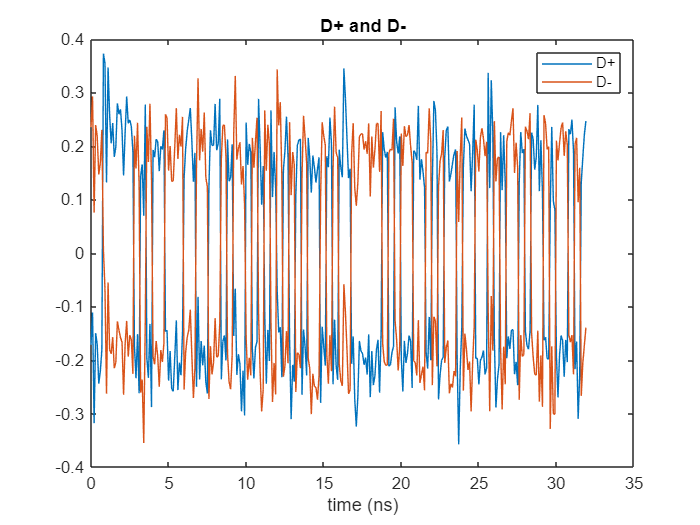

clear; clc;

%% Save location (the .m file and the .txt files all live in RX)
cd('C:/GraduationProject/Serial-Link-PHY-GP/RTL/RX')

%% Parameters
Rb  = 2.5e9;
os  = 4;                 % 1 sample = 100 ps
fs  = Rb*os;
Vcm = 0;
A   = 0.2;

%% Symbols (10 bits each)
K28n = [0 0 1 1 1 1 1 0 1 0];     % K28.5 comma, RD-
K28p = [1 1 0 0 0 0 0 1 0 1];     % K28.5 comma, RD+

pool = [1 1 0 0 0 1 1 0 0 1;      % D3.1
        1 0 1 0 0 1 0 1 0 1;      % D5.2
        0 1 0 1 0 1 1 0 1 0;      % D10.5
        0 0 1 1 0 1 0 1 1 0;      % D12.6
        1 1 0 0 1 0 1 0 0 1;      % D19.1
        0 1 1 0 1 0 0 1 0 1;      % D22.2
        1 0 0 1 1 0 1 0 1 0;      % D25.5
        0 1 1 1 0 0 0 1 1 0];     % D14.6

%% Stream: each set = comma + 3 data symbols from the pool
nsets = 8;                        % keep it even
bits  = [];
idx   = 0;
for k = 1:nsets
    if mod(k,2) == 1, comma = K28n; else, comma = K28p; end   % commas alternate
    sel  = mod(idx:idx+2, size(pool,1)) + 1;                  % next 3 pool rows
    idx  = idx + 3;
    body = reshape(pool(sel,:).', 1, []);                     % rows -> one long row
    bits = [bits comma body];
end

%% Stimulus: D+ and D-
s  = repelem(2*bits - 1, os);
cm_noise = 0.05*randn(size(s));
Dp = Vcm + A*s + cm_noise + 0.01*randn(size(s));
Dn = Vcm - A*s + cm_noise + 0.01*randn(size(s));

%% Export
fid = fopen('rx_in_real.txt','w');
fprintf(fid, '%.9f %.9f\n', [Dp(:), Dn(:)].');
fclose(fid);

%% Plot
nb = 80;  ns = nb*os;
t  = (0:ns-1)/fs*1e9;
plot(t, Dp(1:ns), t, Dn(1:ns));
title('D+ and D-'); legend('D+','D-'); xlabel('time (ns)');